# kalman filtering tutorial

Harrison Ritz April 2021

based on kalmanfilter.m from [http://www.diedrichsenlab.org/toolboxes/toolbox_kinematics.htm](http://www.diedrichsenlab.org/toolboxes/toolbox_kinematics.htm)

resources:

[https://youtube.com/playlist?list=PLX2gX-ftPVXU3oUFNATxGXY90AULiqnWT](https://youtube.com/playlist?list=PLX2gX-ftPVXU3oUFNATxGXY90AULiqnWT)

[www.kalmanfilter.net](www.kalmanfilter.net)

clear; clc; close all;

# UNIVARIATE 

## univariate filtering

P: estimate (reducable) uncertainty 

R: measurement (irreducable) uncertainty


$$K_{t} = P_{t} / (P_{t} + R)$$


**estimate updates **

prediction: $x_{t} = x_{t} + K_{t}(y_{t} - x_{t-1})$ 

uncertainty: $P_{t} = P_{t-1} - K_{t}P_{t-1}$

**time updates**

Q: state noise  

prediction: $x_{t+1} + Ax_{t} + [Bu]$ 

uncertainty: $P_{t+1} + AP_{t}A' + Q$

## generate random walk

% === setup
nTime       = 100;
a_gen       = .95;
sd_gen      = 1;
y = 0;


% === run
for tt = 1:(nTime-1)
    
    y(tt+1) = a_gen*y(tt) + randn*sd_gen;
    
end


% === plot
figure; hold on;
plot(y, '-k', 'LineWidth', 2);
set(gca, 'LineWidth', 1, 'TickDir', 'out');

title(sprintf('1d random walk (a=%g, sd=%g)', a_gen, sd_gen))
xlabel('timesteps')
ylabel('y')

## kalman filter 

P: estimate uncertainty 

R: measurement uncertainty

Q: state noise  

% === setup
A =  a_gen;
Q =  a_gen*sd_gen*a_gen';
R =  1;

xm = 0;
Pm = 5;


% === run
clear yp K x P
for tt = 1:nTime
    
    % Predict
    yp(tt)  = xm;
    K(tt)   = Pm ./ (Pm + R);
    
    % Measurement update
    x(tt)   = xm + K(tt)*(y(tt) - xm);
    P(tt)   = Pm - K(tt)*Pm;
    
    % Time update
    xm      = A*x(tt);
    Pm      = A*P(tt)*A' + Q;
    
end


% === plot
figure; hold on;

% plot PE timeseries
nexttile; hold on;
plot(y, '-k', 'LineWidth', 2);
plot(yp + P, '-r', 'LineWidth', .5);
plot(yp,  '-r', 'LineWidth', 1.5);
plot(yp - P, '-r', 'LineWidth', .5);

% errorbar(yp, P, '.r', 'LineWidth', 1, 'MarkerFaceColor', 'r');


set(gca, 'LineWidth', 1, 'TickDir', 'out');

title(sprintf('kalman fit random walk (A=%g, Q=%g, R=%g)', A, Q, R))
xlabel('timesteps')
ylabel('y')


% plot diagnostics
figure; hold on;
tiledlayout(1,2)

% % plot PE distribution
% nexttile; hold on;
% [f,x]=ksdensity(y-yp);
% plot(x, f, '-k', 'LineWidth',2);
% 
% xlim([-5, 5])
% 
% title(sprintf('PE distribution'))
% xlabel('PE')
% ylabel('density')


% plot gain timeseries
nexttile; hold on;
plot(K, '-k', 'LineWidth',2);

title(sprintf('gain timeseries'))
xlabel('timesteps')
ylabel('gain')


% plot uncertainty timeseries
nexttile; hold on;
plot(P, '--k', 'LineWidth',2);

title(sprintf('uncertainty timeseries'))
xlabel('timesteps')
ylabel('uncertainty')

# MULTIVARIATE

## multivariate filtering

P: estimate uncertainty 

R: measurement uncertainty 

C: observation matrix 


$$K_{t} = P_{t}C'(CP_{t}C' + R)^{-1}$$


**estimate updates **

prediction: $x_{t} = x_{t} + K(y_{t} - Cx_{t-1})$ 

uncertainty: $P_{t} = P_{t-1} - K_{t} CP_{t-1}$

**time updates **

Q: state noise  

prediction: $x_{t+1} + Ax_{t} + [Bu]$ 

uncertainty: $P_{t+1} + AP_{t}A' + Q$

## generate velocity + random walk 

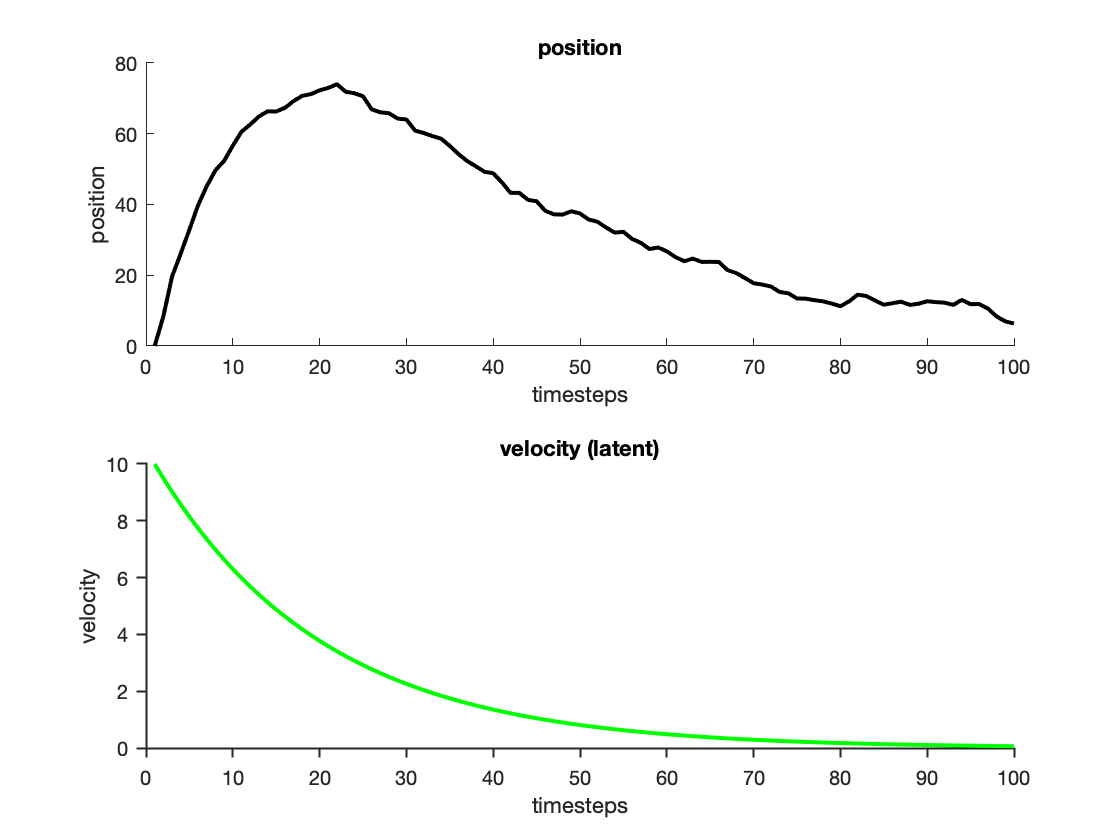

% === setup
nTime   = 100;

a_gen   = [...
    .95  1;...
     0 .95];

sd_gen  = [...
    1, 0;...
    0, 0];

y = [...
    0;...
    10];


% === run
for tt = 1:(nTime-1)
    
    y(:,tt+1) = a_gen*y(:,tt) + sd_gen*randn(2,1);
    
end


% === plot
figure; hold on;
nexttile; hold on;
plot(y(1,:), '-k', 'LineWidth', 2);
title(sprintf('position'));
xlabel('timesteps')
ylabel('position')

nexttile; hold on;
plot(y(2,:), '-g', 'LineWidth', 2);
title(sprintf('velocity (latent)'));
xlabel('timesteps')
ylabel('velocity')


set(gca, 'LineWidth', 1, 'TickDir', 'out');

## kalman filter 

P: estimate uncertainty 

R: measurement uncertainty

Q: state noise  

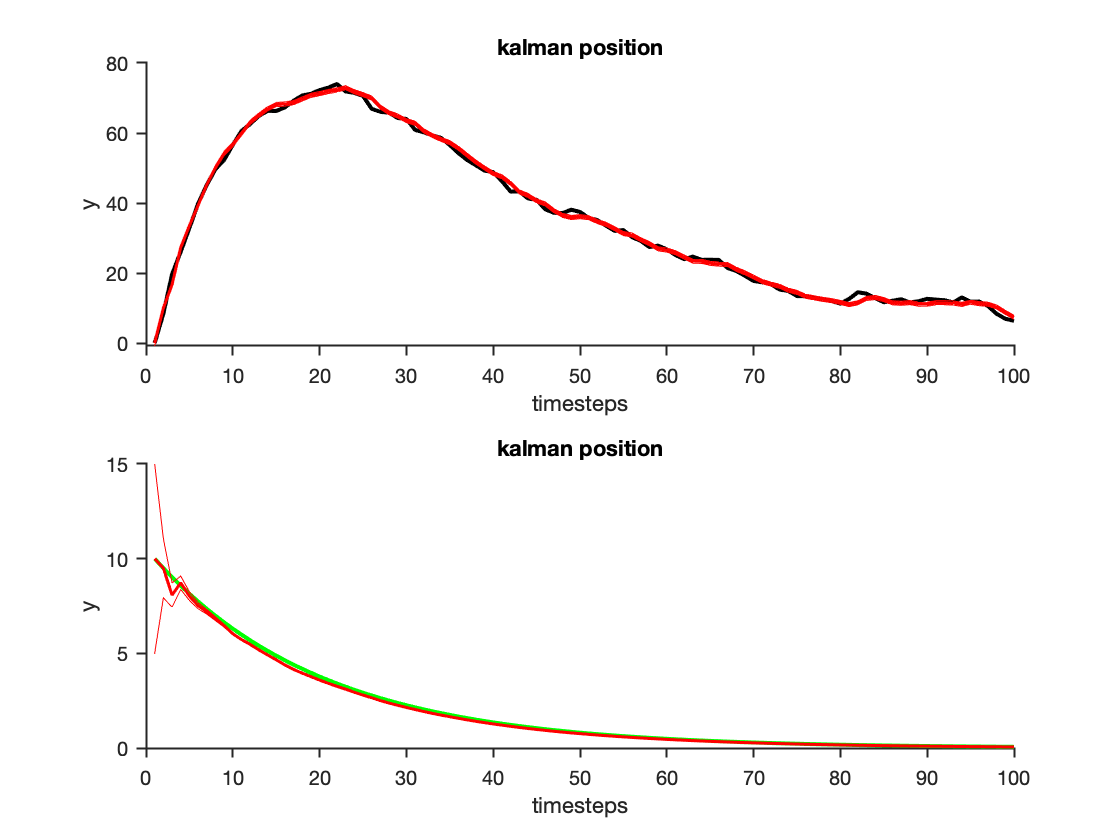

% === setup
A =  a_gen;

Q = a_gen*(sd_gen)*a_gen';

R =  [...
      1, 0;...
      0, 1];

C =  [...
    1, 0;...
    0, 0];

xm = [...
    0;
   10];

Pm = [...
    5, 0;...
    0, 5];


% === run
clear yp yAll K x P
for tt = 1:nTime
    
    % Predict
    yp(:,tt)    = xm;
    K(:,:,tt)   = Pm*C' * inv(C*Pm*C' + R);
    
    % Measurement update
    x(:,tt)   = xm + K(:,:,tt)*(y(:,tt) - C*xm);
    P(:,:,tt)   = Pm - K(:,:,tt)*C*Pm;
    
    % Time update
    xm      = A*x(:,tt);
    Pm      = A*P(:,:,tt)*A' + Q;
    
    
end


% === plot
figure; hold on;
tiledlayout(2,1)


% plot timeseries
nexttile; hold on;
plot(y(1,:), '-k', 'LineWidth', 2);
plot(yp(1,:) + squeeze(P(1,1,:))', '-r', 'LineWidth', .5);
plot(yp(1,:),  '-r', 'LineWidth', 1.5);
plot(yp(1,:) - squeeze(P(1,1,:))', '-r', 'LineWidth', .5);


set(gca, 'LineWidth', 1, 'TickDir', 'out');

title(sprintf('kalman position'))
xlabel('timesteps')
ylabel('y')


nexttile; hold on;
plot(y(2,:), '-g', 'LineWidth', 2);
plot(yp(2,:) + squeeze(P(2,2,:))', '-r', 'LineWidth', .5);
plot(yp(2,:),  '-r', 'LineWidth', 1.5);
plot(yp(2,:) - squeeze(P(2,2,:))', '-r', 'LineWidth', .5);


set(gca, 'LineWidth', 1, 'TickDir', 'out');

title(sprintf('kalman position'))
xlabel('timesteps')
ylabel('y')

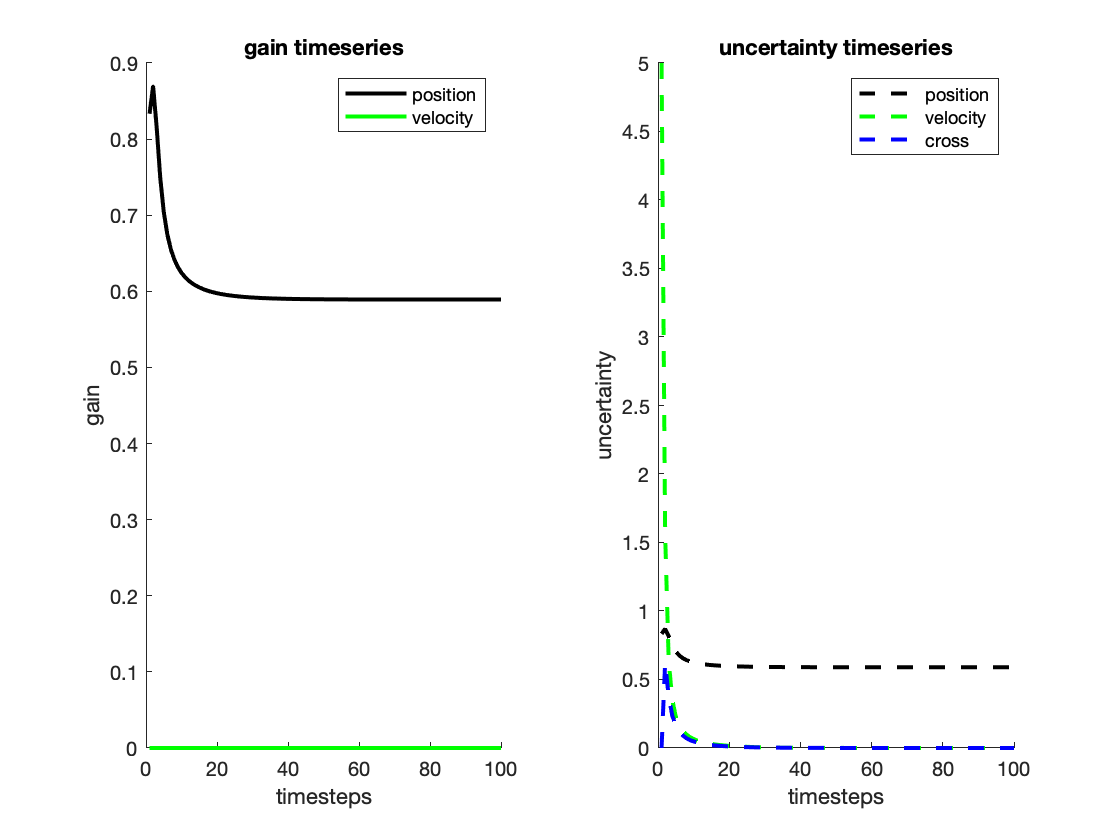










% plot diagnostics
figure; hold on;
tiledlayout(1,2)


% plot gain timeseries
nexttile; hold on;
plot(squeeze(K(1,1,:)), '-k', 'LineWidth',2);
plot(squeeze(K(2,2,:)), '-g', 'LineWidth',2);

title(sprintf('gain timeseries'))
xlabel('timesteps')
ylabel('gain')
legend({'position', 'velocity'})

% plot uncertainty timeseries
nexttile; hold on;
plot(squeeze(P(1,1,:)), '--k', 'LineWidth',2);
plot(squeeze(P(2,2,:)), '--g', 'LineWidth',2);
plot(squeeze(P(1,2,:)), '--b', 'LineWidth',2);

title(sprintf('uncertainty timeseries'))
xlabel('timesteps')
ylabel('uncertainty')
legend({'position', 'velocity', 'cross'})